# Lab 4 by Cole Bardin     Section 62

## Parameterized Systems of Equations

## Question 1

% Clear the workspace, clear the command window and close all windows.
clear, clc, close all
% Declare the parameter m to be symbolic.
syms m
% Enter A(m) using an anonymous function as shown below.
A = @(m) [ m -1; (3*m - m^3) (1-3*m^2)];

% Test A func
disp("Testing A function:")

Testing A function:


disp("A(-1)=")

A(-1)=


disp(A(-1))

    -1    -1
    -2    -2



disp("A(0)=")

A(0)=


disp(A(0))

     0    -1
     0     1



disp("A(1)=")

A(1)=


disp(A(1))

     1    -1
     2    -2




% Now enter b(m) using another anonymous function. 
b = @(m) 2*(1-m) * [1; (m^2+4*m +1) ];

disp("Determinant of A(m) =")

Determinant of A(m) =


disp(det(A(m)))

$$4\,m-4\,m^{3}$$


% Question 2
% Make equation when det(A(m)) is zero
f = matlabFunction( det(A(m)) );
eqn = f(m) == 0;
% Use solve func to get solutions
disp("Values of m where det(A(m)) is 0:")

Values of m where det(A(m)) is 0:


disp(solve(eqn))

$$\left(\begin{array}{c} -1\\ 0\\ 1 \end{array}\right)$$


% Question 3
hold on

% Generate x values from -2.5 to 2.5 with a step of 0.1
x = -2.5 : 0.1 : 2.5;
% Use func to create y values for all x
y = f(x);

% Use logical indexing to get x values when f(x) is 0
x_zeros = x(f(x)==0);

% Plot all the x and y values
plot(x,y,'g','LineWidth',3)

plot(x_zeros(1), 0, 'bo', 'MarkerSize',12,'MarkerFaceColor','r')
plot(x_zeros(2), 0, 'bo', 'MarkerSize',12,'MarkerFaceColor','r')
plot(x_zeros(3), 0, 'bo', 'MarkerSize',12,'MarkerFaceColor','y')

xlabel("Parameter m")
ylabel("Determinant of A")
title("Number of Solutions")

% Question 4
f = matlabFunction( det(A(m)) );

% m = -1
AM = [A(-1), b(-1)];
disp("RREF of AM with m=-1:")

RREF of AM with m=-1:


disp(rref(AM))

     1     1     0
     0     0     1




% m = 1
AM = [A(1), b(1)];
disp("RREF of AM with m=1:")

RREF of AM with m=1:


disp(rref(AM))

     1    -1     0
     0     0     0




% Question 5
% m = 0
AM = [A(0), b(0)];
disp("RREF of AM with m=0:")

RREF of AM with m=0:


disp(rref(AM))

     0     1     0
     0     0     1




% Question 6
m6 = tand(sym(105));

% Solution with m = m6
AM = [A(m6), b(m6)];
disp("Simplified AM with m=m6:")

Simplified AM with m=m6:


disp(simplify(AM))

$$\left(\begin{array}{ccc} -\sqrt{3}-2 & -1 & 2\,\sqrt{3}+6\\ 12\,\sqrt{3}+20 & -12\,\sqrt{3}-20 & 0 \end{array}\right)$$

disp("Simplified RREF of AM with m=m6:")

Simplified RREF of AM with m=m6:


disp(simplify(rref(AM)))

$$\left(\begin{array}{ccc} 1 & 0 & -2\\ 0 & 1 & -2 \end{array}\right)$$


% Question 7
% General Solution
AM = [A(m), b(m)];
AM_s = simplify(AM);
disp("Simplified RREF of AM general Solution=")

Simplified RREF of AM general Solution=


disp(simplify(rref(AM_s)))

$$\left(\begin{array}{ccc} 1 & 0 & \frac{-m^{2}+2\,m+1}{m\,\left(m+1\right)}\\ 0 & 1 & \frac{m^{2}+2\,m-1}{m+1} \end{array}\right)$$


disp("Number of solutions when m=1:")

Number of solutions when m=1:


disp(number_of_solutions(A(1),b(1)))

   Inf




disp("Number of solutions when m=0:")

Number of solutions when m=0:


disp(number_of_solutions(A(0),b(0)))

     0




disp("Number of solutions when m=-1:")

Number of solutions when m=-1:


disp(number_of_solutions(A(-1),b(-1)))

     0



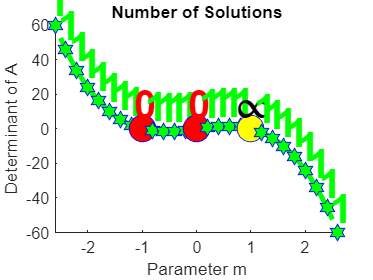


% Question 8
dx = 0.05; dy = 0.25;
for m = -2.6 : 0.2 : 2.6
    n = number_of_solutions(A(m), b(m));
    if f(m) == 0
        zero_marker = plot(m, 0, 'bo', 'MarkerSize', 16, 'MarkerFaceColor', 'white');
    else
        plot(m, f(m), 'bh', 'MarkerSize', 10, 'MarkerFaceColor', 'green')
    end
        the_text = text(m+dx, f(m) + dy, num2str(n), 'FontSize', 24) ;
        the_text.set('FontWeight', 'bold', 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom');
        % Auto Color Code the Zero Markers and the Text
    if n==0 % inconsistent! No solutions
        the_text.set('Color', 'red')
        % Set the MarkerFaceColor for zero_marker to red
        zero_marker.set("MarkerFaceColor", 'red')
    elseif n==inf % there are free variables
        the_text.set('string', '\infty')
        % Set the MarkerFaceColor for zero_marker to yellow
        zero_marker.set("MarkerFaceColor", 'yellow')
    else
        the_text.set('Color', 'green') % unique solution!
    end
end


% Question 9
deg = 180 + atan(3^(1/2)-2)*180/pi;
disp("Degree blue line makes with horizontal axis:")

Degree blue line makes with horizontal axis:


disp(deg)

   165




% Question 10
% Reset m as a symbol since previous questions set it as a number
syms m;
% Make A and b matrices
Am = A(m);
bm = b(m);
% Get determinant of A matrix
det_A = det(Am);

% Replace first col of A with B, save as new var A1
A1 = Am;
A1(:,1) = bm;
% Apply Cramer's Rule to determine solution for x1
x1 = simplify(det(A1)/det_A);
disp("Using Cramer's Rule, x1 =")

Using Cramer's Rule, x1 =


disp(x1)

$$\frac{-m^{2}+2\,m+1}{m\,\left(m+1\right)}$$


% Replace second col of A with B, save as new var A2
A2 = Am;
A2(:,2) = bm;
% Apply Cramer's Rule to determine solution for x2
x2 = simplify(det(A2)/det_A);
disp("Using Cramer's Rule, x2 =")

Using Cramer's Rule, x2 =


disp(x2)

$$\frac{m^{2}+2\,m-1}{m+1}$$